# Continuous Choices: Euler-Equation GMM

**Prepared by Aaron Barkley, University of Melbourne**

This Live Script develops a structural estimator from an economic model, then implements it step by step. The exercise is inspired by Hansen and Singleton (1982), but uses modern public data and simplified Treasury returns. It is a teaching illustration, not a replication of their data or empirical specification.

clear; clc; close all

## 1. The consumer's problem

A representative consumer chooses consumption $C_t$ and asset holdings $Q_t$ to maximize expected discounted utility,


$$E_0\left[\sum_{t=0}^{\infty}\beta^t u(C_t)\right],
 \qquad 0<\beta<1.$$


For one asset with price $P_t$, dividend $D_t$, and income $W_t$, the period budget constraint can be written as


$$C_t+P_tQ_t\leq(P_t+D_t)Q_{t-1}+W_t.$$


Buying one more unit at time $t$ costs $P_tu'(C_t)$ in marginal utility. Its expected discounted payoff next period is $\beta E_t[(P_{t+1}+D_{t+1})u'(C_{t+1})]$. At an interior optimum these quantities are equal:


$$P_tu'(C_t)=\beta E_t[(P_{t+1}+D_{t+1})u'(C_{t+1})].$$


Define the gross real return $R_{t+1}=(P_{t+1}+D_{t+1})/P_t$. Dividing by $P_tu'(C_t)$ gives the Euler equation


$$E_t\left[\beta\frac{u'(C_{t+1})}{u'(C_t)}R_{t+1}-1\right]=0.$$


This first-order condition is the link between the consumer's structural preference parameters and observed consumption growth and asset returns.

## 2. Parametric pricing restrictions

We use constant-relative-risk-aversion (CRRA) utility,


$$u(C_t)=\frac{C_t^{1-\gamma}}{1-\gamma},\qquad \gamma>0.$$


Since $u'(C_t)=C_t^{-\gamma}$, the ratio of marginal utilities depends only on gross consumption growth $g_{t+1}=C_{t+1}/C_t$. The stochastic discount factor and the pricing error for asset $j$ are therefore


$$M_{t+1}(\theta)=\beta g_{t+1}^{-\gamma},\qquad
 e_{t+1,j}(\theta)=M_{t+1}(\theta)R_{t+1,j}-1,$$


where $\theta=(\beta,\gamma)'$. At the true parameter, $E_t[e_{t+1,j}(\theta_0)]=0$ for every correctly priced asset.

In the code, `pricing_errors` implements these two equations. It first constructs the $n\times1$ vector of stochastic discount factors and then returns an $n\times2$ matrix of pricing errors, one column for each asset.

## 3. From conditional restrictions to GMM moments

The Euler equation is conditional on information available at time $t$. If the instrument vector $Z_t$ is part of that information set, the law of iterated expectations implies


$$E_t[e_{t+1,j}(\theta_0)]=0
 \quad\Longrightarrow\quad
 E[Z_te_{t+1,j}(\theta_0)]=0.$$


We use four instruments: a constant, lagged bill and bond returns, and lagged consumption growth. For two assets, the observation-level moment vector is


$$g_t(\theta)=
 \left[\begin{array}{c}
 Z_te_{t+1,1}(\theta)\\
 Z_te_{t+1,2}(\theta)
 \end{array}\right],\qquad K=2\times4=8.$$


The function `stacked_moments` performs this multiplication. Its output `U` has one row per observation and eight columns. The first four columns are the bill pricing error multiplied by each instrument; the last four repeat the construction for the bond. The sample moments are the column means,


$$\bar g_n(\theta)=\frac{1}{n}\sum_{t=1}^{n}g_t(\theta).$$


## 4. The GMM objective

With more moments than parameters, it is generally impossible to make every sample moment exactly zero. GMM instead selects parameters that make the moments jointly close to zero according to a positive-definite weighting matrix $W$:


$$Q_n(\theta;W)=\bar g_n(\theta)'W\bar g_n(\theta),\qquad
 \hat\theta(W)=\arg\min_{\theta}Q_n(\theta;W).$$


The function `gmm_objective` is a direct translation of this equation: it calls `stacked_moments`, averages the rows to obtain $\bar g_n(\theta)$, and evaluates the quadratic form. Thus each optimizer evaluation traces back to the CRRA Euler equation above.

We use two-step GMM. The first step sets $W_1=I_8$. At its estimate $\tilde\theta$, we use `nw_cov` to estimate the long-run covariance matrix $\widehat S$ of $g_t(\tilde\theta)$ with four Newey-West lags. The second step uses $W_2=\widehat S^{-1}$ and minimizes the same criterion again.

## 5. Data and empirical timing

The sample is quarterly from 1962Q1 through 2019Q4. The local files are public FRED snapshots for real consumption per capita, the three-month Treasury bill rate, the ten-year Treasury yield, and the CPI. Setting `readLocal=false` downloads the same series directly from FRED.

The three-month bill return is constructed from the discount rate. The bond return treats the ten-year yield as a simplified constant-maturity zero-coupon holding return. CPI inflation converts both to real gross returns. These choices keep the illustration public and compact, but they are not the assets used in the original paper.

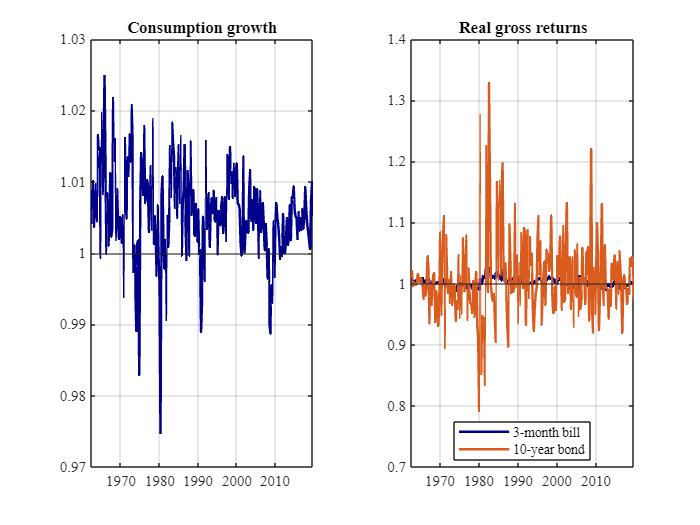

readLocal = true;
scriptFile = matlab.desktop.editor.getActiveFilename;
if isempty(scriptFile)
    scriptFile = mfilename('fullpath');
end
dataPath = fullfile(fileparts(scriptFile),'..','Data');
series = {'A794RX0Q048SBEA','DTB3','DGS10','CPIAUCSL'};
% A794RX0Q048SBEA: real consumption per capita, used to construct g_{t+1}.
% DTB3: 3-month Treasury bill discount rate, used for the short safe return.
% DGS10: 10-year Treasury yield, used for the simplified bond return.
% CPIAUCSL: consumer price index, used to convert returns from nominal to real.

if readLocal
    C = read_series(fullfile(dataPath,[series{1} '.csv']));
    bill = read_series(fullfile(dataPath,[series{2} '.csv']));
    bond = read_series(fullfile(dataPath,[series{3} '.csv']));
    cpi = read_series(fullfile(dataPath,[series{4} '.csv']));
else
    C = fred_series(series{1});
    bill = fred_series(series{2});
    bond = fred_series(series{3});
    cpi = fred_series(series{4});
end

C = retime(table2timetable(rmmissing(C)),'quarterly','lastvalue');
bill = retime(table2timetable(rmmissing(bill)),'quarterly','lastvalue');
bond = retime(table2timetable(rmmissing(bond)),'quarterly','lastvalue');
cpi = retime(table2timetable(rmmissing(cpi)),'quarterly','lastvalue');

C.Properties.VariableNames = {'consumption'};
bill.Properties.VariableNames = {'billYield'};
bond.Properties.VariableNames = {'bondYield'};
cpi.Properties.VariableNames = {'cpi'};
Data = synchronize(C,bill,bond,cpi,'intersection');
Data = Data(timerange(datetime(1962,1,1),datetime(2019,12,31),'closed'),:);

gAll = Data.consumption(2:end)./Data.consumption(1:end-1); % g_{t+1}=C_{t+1}/C_t
inflation = Data.cpi(2:end)./Data.cpi(1:end-1);            % gross CPI inflation

disc = Data.billYield(1:end-1)/100;                 % annualized bill discount yield
RfAll = (1./(1-disc*91/360))./inflation;            % real gross bill return R_{t+1,1}

y0 = Data.bondYield(1:end-1)/400;                   % quarterly yield at t
y1 = Data.bondYield(2:end)/400;                     % quarterly yield at t+1
RbAll = ((1+y1).^(-39)./(1+y0).^(-40))./inflation; % real gross bond return R_{t+1,2}

n = length(gAll)-1;
gC = gAll(2:end); % consumption growth entering the stochastic discount factor
R = [RfAll(2:end), RbAll(2:end)]; % two returns in the Euler pricing errors
X = [ones(n,1), RfAll(1:end-1), RbAll(1:end-1), gAll(1:end-1)]; % instruments Z_t

figure
tiledlayout(1,2)
nexttile; plot(Data.Time(2:end),gAll); yline(1); title('Consumption growth')
nexttile; plot(Data.Time(3:end),R); yline(1); title('Real gross returns')
legend('3-month bill','10-year bond','Location','best')

## 6. Matching the data arrays to the equations

Each row of `gC` and `R` contains the consumption growth and two returns entering $e_{t+1,j}(\theta)$. The corresponding row of `X` contains the instrument vector $Z_t$: a constant and the preceding period's returns and consumption growth. Dropping the first usable pricing observation is what makes these instruments lagged rather than contemporaneous.

The dimensions provide useful checks. `gC` is $n\times1$, `R` is $n\times2$, and `X` is $n\times4$. Consequently `pricing_errors` returns $n\times2$, while `stacked_moments` returns $n\times8$.

## 7. Two-step estimation

The anonymous functions below pass the data and a chosen weighting matrix into `gmm_objective`. The optimizer changes only $\theta$. After the first estimate, `U` stores the eight observation-level moments evaluated at $\tilde\theta$; these are the inputs to the Newey-West covariance estimator.

theta0 = [0.99; 5];
L = size(X,2);
W1 = eye(2*L);
options = optimoptions('fminunc','Display','off','Algorithm','quasi-newton');

obj1 = @(theta) gmm_objective(theta,W1,gC,R,X);
[theta1,~,exit1] = fminunc(obj1,theta0,options);

U = stacked_moments(theta1,gC,R,X);
S = nw_cov(U,4);
W2 = S\eye(size(S));
obj2 = @(theta) gmm_objective(theta,W2,gC,R,X);
[theta,~,exit2] = fminunc(obj2,theta1,options);

## 8. Standard errors and specification test

Let


$$D=\left.\frac{\partial\bar g_n(\theta)}{\partial\theta'}
 \right|_{\theta=\hat\theta}.$$


The function `numerical_jacobian` approximates $D$ with centered finite differences. Because $W_2=\widehat S^{-1}$, the efficient two-step covariance estimator is


$$\widehat V(\hat\theta)=
 (D'W_2D)^{-1}/n.$$


Finally, the overidentification statistic evaluates the minimized GMM criterion:


$$J=n\,\bar g_n(\hat\theta)'W_2\bar g_n(\hat\theta)
 \ \overset{a}{\sim}\ \chi^2_{K-p}.$$


Here $K=8$ moments and $p=2$ parameters, so the reference distribution has six degrees of freedom. The reported p-value is the upper-tail probability $Pr(\chi^2_6\geq J)$.

g = mean(stacked_moments(theta,gC,R,X),1)';
D = numerical_jacobian(@(x) mean(stacked_moments(x,gC,R,X),1)',theta);
V = (D'*W2*D)\eye(2)/n;
se = sqrt(diag(V));
J = n*g'*W2*g;
df = 2*L-length(theta);
pValue = 1-chi2cdf(J,df);

fprintf('\nHansen-Singleton teaching illustration (quarterly)\n')


Hansen-Singleton teaching illustration (quarterly)


fprintf('beta  = %.4f  (se %.4f)\n',theta(1),se(1))

beta  = 1.0067  (se 0.0068)


fprintf('gamma = %.4f  (se %.4f)\n',theta(2),se(2))

gamma = 1.3659  (se 1.0073)


fprintf('J     = %.2f  (df %d, p %.3f)\n',J,df,pValue)

J     = 4.87  (df 6, p 0.560)


if exit1 <= 0 || exit2 <= 0
    warning('At least one GMM optimization did not report convergence.')
end
if theta(1) <= 0 || theta(1) >= 1 || theta(2) <= 0
    warning('The unrestricted estimate is outside beta in (0,1), gamma > 0.')
end

## 9. Reading the results

The optimization is deliberately unrestricted. In the reference run, the estimate of $\beta$ lies slightly above the model's admissible region. This is a specification diagnostic rather than a valid discount factor; possible explanations include sampling variation, weak identification, simplified return construction, or model misspecification. Likewise, a failure to reject the overidentifying restrictions does not prove that the model is correct.

## Data input functions

`read_series` standardizes a local CSV or FRED response to the same two columns. `fred_series` supplies the online URL when `readLocal=false`.

function T = read_series(file)
T = readtable(file);
T = T(:,1:2);
T.Properties.VariableNames = {'Time','Value'};
T.Time = datetime(T.Time,'InputFormat','yyyy-MM-dd');
end

function T = fred_series(id)
url = ['https://fred.stlouisfed.org/graph/fredgraph.csv?id=' id];
T = read_series(url);
end

## Euler errors and moment rows

`pricing_errors` implements $e_{t+1,j}(\theta)=\beta g_{t+1}^{-\gamma}R_{t+1,j}-1$. `stacked_moments` then implements $g_t(\theta)=[Z_te_{t+1,1};Z_te_{t+1,2}]$ for every sample row.

function errors = pricing_errors(theta,gC,R)
sdf = theta(1)*gC.^(-theta(2));
errors = sdf.*R-1;
end

function U = stacked_moments(theta,gC,R,X)
errors = pricing_errors(theta,gC,R);
U = [X.*errors(:,1), X.*errors(:,2)];
end

## GMM criterion and long-run covariance

`gmm_objective` implements $Q_n(\theta;W)=\bar g_n(\theta)'W\bar g_n(\theta)$. `nw_cov` centers the moment rows and estimates $\widehat S$ using Bartlett weights. The second step above solves $W_2\widehat S=I$ rather than forming an explicit matrix inverse.

function q = gmm_objective(theta,W,gC,R,X)
g = mean(stacked_moments(theta,gC,R,X),1)';
q = g'*W*g;
end

function S = nw_cov(U,L)
U = U-mean(U,1);
[n,~] = size(U);
S = U'*U/n;
for ell = 1:L
    G = U(ell+1:end,:)'*U(1:end-ell,:)/n;
    S = S+(1-ell/(L+1))*(G+G');
end
end

## Numerical derivative

`numerical_jacobian` returns the matrix $D$ used in the covariance formula. Each column perturbs one component of $\theta$ while holding the other fixed.

function D = numerical_jacobian(fun,theta)
g0 = fun(theta);
D = zeros(length(g0),length(theta));
for j = 1:length(theta)
    h = 1e-6*max(1,abs(theta(j)));
    step = zeros(size(theta)); step(j) = h;
    D(:,j) = (fun(theta+step)-fun(theta-step))/(2*h);
end
end